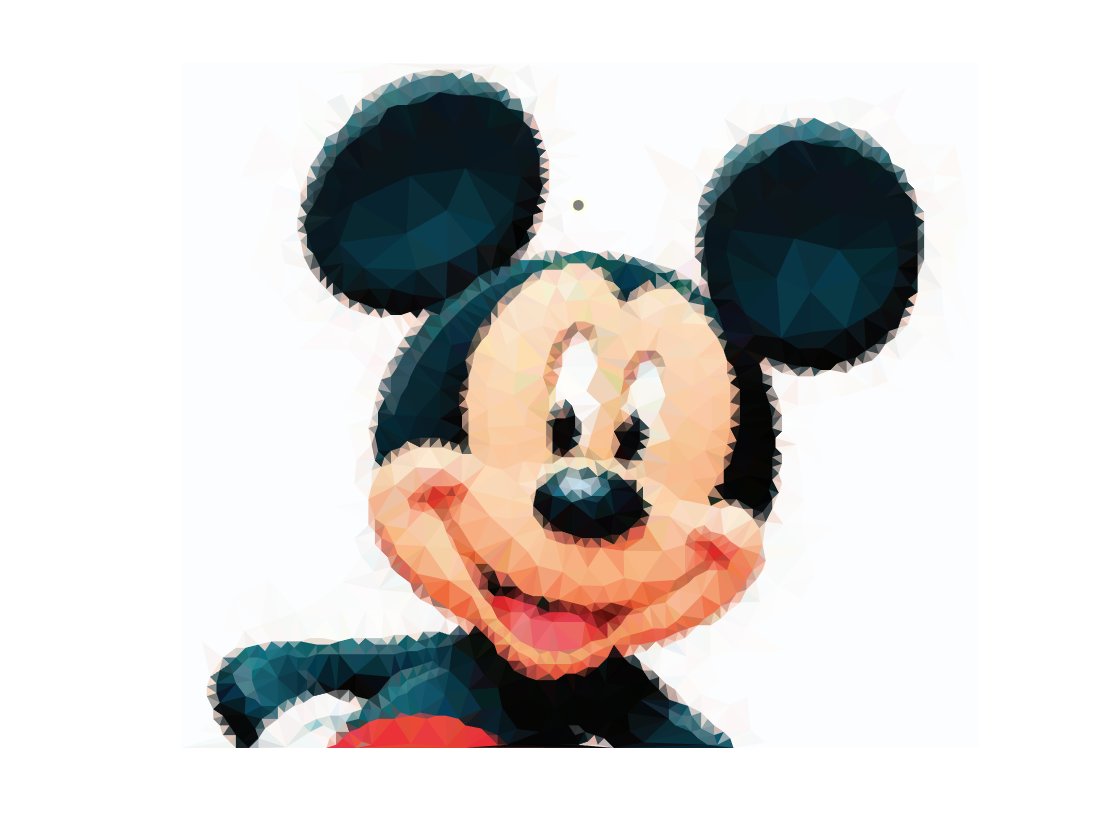

clear all; clc;
%% 读入图像
Origin = imread('t4.png');
%% 转成灰度图
% 由于边缘检测是根据灰度突变来分割图像，只需要灰度图就够了。
% 而彩色图信息量大，运算速度慢。故先转成灰度图。
% 若原图已经是灰度图，rgb2gray会报错，所以要判断一下。
if size(Origin,3)==3
    Gray = rgb2gray(Origin);
else
    Gray = Origin;
end
% imshow(Gray)

%% 边缘检测
% 为什么不用库的edge和imfilter？
% 因为这两个返回的是01矩阵，不是灰度矩阵，不方便对细节做处理
% Boundary = edge(Gray,'Sobel'); % 库自带
% Boundary = edge(Gray,'Canny'); % Canny边缘检测
Boundary = sobel_detect(Gray);
% imshow(Boundary)

%% 随机采样+三角剖分
% Delaunay三角剖分要求每一个三角形的外接圆圆内不能存在点集内的其它任何一点
% 泊松圆盘采样以每个点为圆心以一定半径画圆，圆内不会包含其他点
% 泊松圆盘采样
% 获取边缘有效点集，0.4可以根据结果调整
edge = Boundary;
max_val = max(max(edge))*0.4;
[edgeX, edgeY] = find(edge >= max_val); % 返回两个列向量
% 获取半径r，在边缘上的半径与在非边缘上的不同
% 网上看到的fast poisson disk sampling都是先确定r，再通过r确定cell的边长(cell_size = r/sqrt(n))
% 通过调参猜出较优的r
% 边缘r
Boundary_size = size(Boundary);
r_edge = min(Boundary_size)/80;
% 非边缘r
r_max = min(Boundary_size)/20;
r_min = min(Boundary_size)/40;

% 在做完边缘采样后，以边缘为起点做非边缘采样
% 边缘采样
edge_point = poisson_edge([edgeY, edgeX], r_edge);
% 非边缘采样
internal_point = poisson_disk(Boundary, edge_point, r_min, r_max);

%imshow(Boundary)
%hold on;
%scatter(internal_point(:,1),internal_point(:,2),3,'filled')
%set(gca,'XTick',[],'YTick',[],'XColor','none','YColor','none')

%scatter(edge_point(:,1),edge_point(:,2),3,'filled')
%set(gca,'XTick',[],'YTick',[],'XColor','none','YColor','none')

% Delaunay三角剖分，直接调用库函数
Delaunay_result = delaunay(internal_point(:,1), internal_point(:,2));

%triplot(Delaunay_result,internal_point(:,1),internal_point(:,2));
%set(gca,'XTick',[],'YTick',[],'XColor','none','YColor','none')

% 重心取色
vector1 = internal_point(Delaunay_result(:,1), :);
vector2 = internal_point(Delaunay_result(:,2), :);
vector3 = internal_point(Delaunay_result(:,3), :);
center = round((vector1+vector2+vector3)./3);
tmp_list = center(:,2)+(center(:,1)-1)*size(Origin,1);
if size(Origin,3) == 3   
    Rchannel = Origin(:,:,1);
    Gchannel = Origin(:,:,2);
    Bchannel = Origin(:,:,3);
    colorList(:,:,1) = Rchannel(tmp_list);
    colorList(:,:,2) = Gchannel(tmp_list);
    colorList(:,:,3) = Bchannel(tmp_list);
else
    colorList(:,:,1) = Origin(tmp_list);
    colorList(:,:,2) = Origin(tmp_list);
    colorList(:,:,3) = Origin(tmp_list);
end

% 图片展示
z=zeros([size(internal_point,1),1]);
trisurf(Delaunay_result,internal_point(:,1),internal_point(:,2),z,'CData',colorList,'EdgeColor','none')
hold on;
set(gca,'XTick',[],'YTick',[],'XColor','none','YColor','none')
axis equal;
set(gca,'YDir','reverse','View',[0,90])

function output_list = poisson_edge(point_set, r)
    % 返回值集合
    random_index_initial = randi([1,size(point_set,1)],1);
    random_point_initial = point_set(random_index_initial,:);
    output_list = random_point_initial;
    % 要处理的点的集合
    processing_list = point_set;

    K = 30;
    
    while ~isempty(processing_list)
        % 从processing_list随机取出一个点
        random_index = randi([1,size(processing_list,1)],1);
        random_point = processing_list(random_index,:);
        % 对该点计算到其他所有点的距离，并找到距离该点[r,2r)的点
        distance = sqrt(sum((point_set - random_point).^2,2));
        neighbour = find(r<=distance & distance<2*r);
        % 取K=30。K越大，得到的结果越紧密
        if length(neighbour) > K
            detect_point = point_set(neighbour(1:K),:);
        else
            detect_point = point_set(neighbour,:);
        end
        % 对需要检测的点，看与已有点之间是否太近，若距离小于r，抛弃
        for index = 1:size(detect_point,1)
            tmp_point = detect_point(index,:);
            tmp_distance = sqrt(sum((output_list-tmp_point).^2,2));
            if all(tmp_distance >= r)
                output_list = [output_list; tmp_point];
                processing_list = [processing_list; tmp_point];
            end
        end
        processing_list(random_index,:) = [];
    end
end

function output_list = poisson_disk(Boundary, edge_point, r_min, r_max)    
    [rows, cols] = size(Boundary);
    
    % 返回值集合
    output_list = [edge_point; 1 1; 1 rows; cols 1; cols rows];
    % 要处理的点的集合
    processing_list = edge_point;
        
    change = double(255 -Boundary);
    cmin = min(min(change));
    cmax = max(max(change));
    rpoint = change - cmin;
    rpoint = rpoint./(cmax-cmin).*(r_max-r_min)+r_min;
    
    K = 30;
    
    while ~isempty(processing_list)
        random_index = randi([1,size(processing_list,1)],1);
        random_point = processing_list(random_index,:);
        ra = rpoint(round(random_point(2)), round(random_point(1)));
        theta = rand(K,1)*2*pi;
        radius = (rand(K,1)+1)*ra;
        x = radius.*cos(theta)+random_point(1);
        y = radius.*sin(theta)+random_point(2);
            
        for i = 1:K
            point = [x(i), y(i)];
            if point(1)>=1 && point(2)>=1 && point(1)<=cols && point(2)<=rows
                distance = sqrt(sum((output_list-point).^2,2));
                if all(distance >= ra)
                    output_list = [output_list;point];
                    processing_list = [processing_list;point];  
                end
            end 
        end
        % 扔掉该随机点
        processing_list(random_index,:) = [];
    end    
end

function boundary = sobel_detect(Gray)
    % Sobel核
    sobelx = [-1 -2 -1; 0 0 0; 1 2 1];
    sobely = [-1 0 1; -2 0 2; -1 0 1];
    
    [rows, cols] = size(Gray);
    tmp = zeros(rows+2, cols+2); % 边沿延拓一格

    % 用原图像的部分填充拓展的格子，能获得较好的效果
    tmp(2:rows+1,2:cols+1) = Gray;
    tmp(1,2:cols+1) = Gray(1,:);
    tmp(2:rows+1,1) = Gray(:,1);
    tmp(rows+2,2:cols+1) = Gray(rows,:);
    tmp(2:rows+1,cols+2) = Gray(:,cols);
    tmp(1,1) = Gray(1,1);
    tmp(rows+2,cols+2) = Gray(rows,cols);
    tmp(rows+2,1) = Gray(rows,1);
    tmp(1,cols+2) = Gray(1,cols);
    
    % 卷积
    Gx = zeros(rows, cols);
    Gy = zeros(rows, cols);
    
    for i = 1:3
        for j = 1:3
            t = tmp(i:rows+i-1,j:cols+j-1);
            Gx = Gx + t.*sobelx(i,j);
            Gy = Gy + t.*sobely(i,j);
        end
    end
    % 输出
    boundary = uint8(sqrt(Gx.^2 + Gy.^2));
end